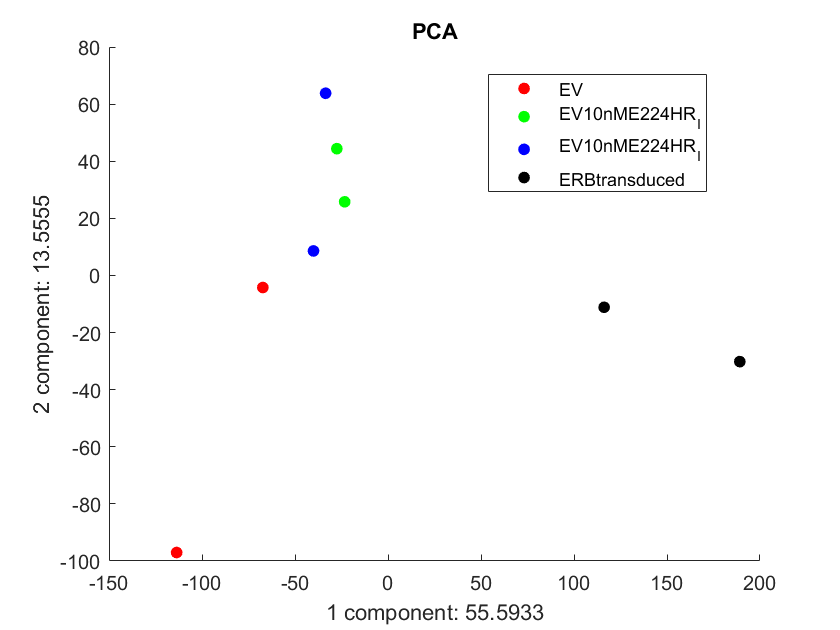

clear all
counts = readtable("C:\Users\maria.pacheco\Documents\GitHub\basicAnalysis\Data\GSE112568_count_table_CRC_C_Williams_Addendum.txt");

lengths = readtable("C:\Users\maria.pacheco\Documents\GitHub\basicAnalysis\Quality Control\R\Output\lengths.txt");
lengths=lengths(:,2:3);

Ensembl= counts.ENSEMBL_ID;
data = log2(table2array(counts(:,3:end))+1);

addpath(genpath(pwd));
cond={'EV', 'EV', 'EV10nME224HR_I',  'EV10nME224HR_I','1uG124hr_I', '1uG124hr_I', 'ERBtransduced','ERBtransduced'};

mapcaplot(data',cond);
[~,score,~,~,explained,~] = pca(data');
figure
hold on
plot(score(1:2,1),score(1:2,2),'r.', 'MarkerSize',20 )
plot(score(3:4,1),score(3:4,2),'g.', 'MarkerSize',20)
plot(score(5:6,1),score(5:6,2),'b.' ,'MarkerSize',20)
plot(score(7:8,1),score(7:8,2),'k.', 'MarkerSize',20)

title('PCA')
xlabel([num2str(1), ' component: ', num2str(explained(1))])
ylabel([num2str(2), ' component: ', num2str(explained(2))])
legend({'EV','EV10nME224HR_I','EV10nME224HR_I', 'ERBtransduced' },'location','best')

boxplot

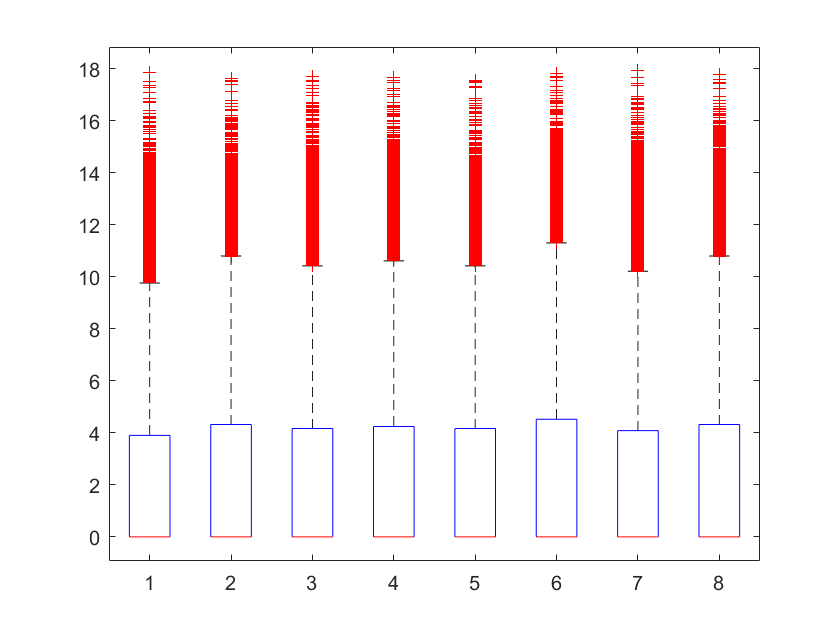

figure
boxplot(data)

[I,IA,IB]=intersect(counts.ENSEMBL_ID,table2array(lengths(:,1)));
data=(data(IA,:));
lengths=table2array(lengths(IB,2));

TPM

temp=data./repmat(lengths,1,size(data,2));
TPM=1000000*temp./repmat(nansum(temp),size(data,1),1);

The sum of TPM for each sample should be 1e6

sum(TPM,1)

ans = 	1.0e+06 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


FPKM

temp=1000000*data./repmat(nansum(data),size(data,1),1);
FPKM=temp./repmat(lengths,1,size(data,2));

Densityplot

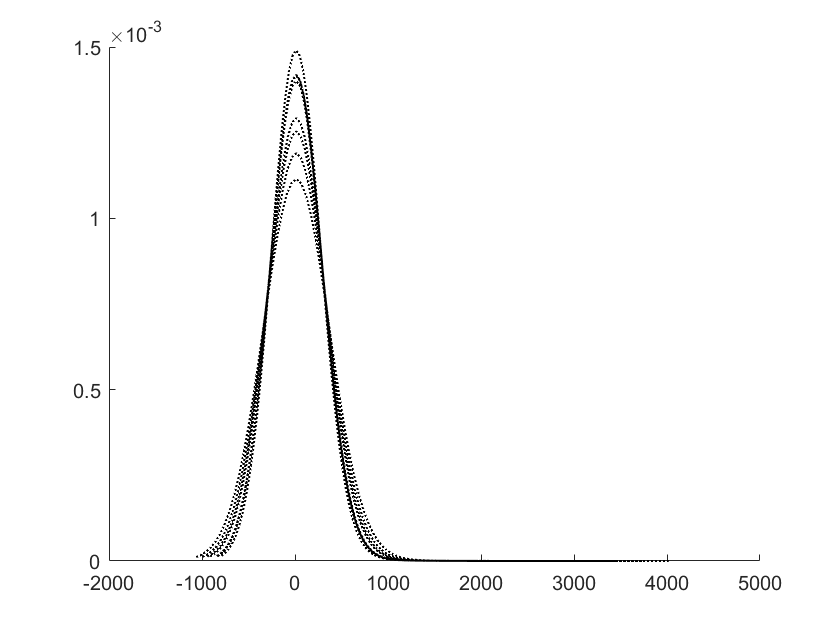

figure
hold on
for i=1:size(TPM,2)    
[probability_estimate,xi] = ksdensity(TPM(:,i));
plot(xi,probability_estimate,':k','LineWidth',1);
end
hold off